# ECE 101 - Plotting

Michael Dekoski

4-25-23

clc
clear

## Opening an Object

soundCard = audiorecorder;  % This is a ref to a soundcard
disp('Recording start')

Recording start


recordblocking(soundCard, 6);
disp('Recording stop')

Recording stop


## View and Analyze Data

soundMag = getaudiodata(soundCard);
soundDeltaT = 1 / 8000;
soundTime = 0:soundDeltaT:6-soundDeltaT;
smoothSound = smoothdata(soundMag, 'movmean', 10);

## Plotting

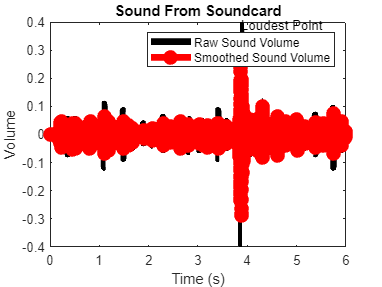

plot(soundTime, soundMag, '-k', soundTime, smoothSound, 'o-r', LineWidth=5)

title('Sound From Soundcard')
xlabel('Time (s)')
ylabel('Volume')
legend('Raw Sound Volume', 'Smoothed Sound Volume')

text(3.867, 0.39, 'Loudest Point')

## Playback

play(soundCard);

## Oscillation with Decay (Simulated)

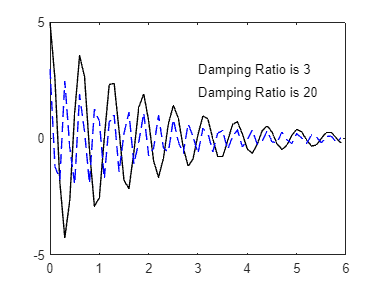

noSoundCardTime = 0:0.1:5.9;
signalAmp1 = 5;     % 
signalFreq1 = 10;   % Hertz

noSoundCardMag = signalAmp1*exp(-0.5*noSoundCardTime).*...
    cos(signalFreq1*noSoundCardTime);

signalAmp2 = 3;
signalFreq2 = 20;

noSoundCardMag2 = signalAmp2*exp(-0.5*noSoundCardTime).*...
    cos(signalFreq2*noSoundCardTime);

plot(noSoundCardTime, noSoundCardMag, '-k',...
    noSoundCardTime, noSoundCardMag2, '--b')

text(3, 3, 'Damping Ratio is 3')
text(3, 2, 'Damping Ratio is 20')